# Monte Carlo Integration

Monte Carlo Integration is a technique of numerical integration using random numbers

- Works best for definite integrals of functions bounded in a certain area

- Desirable technique when integrating higher dimensional expressions

It samples random points in a certain area and determines the proportion that fall within the function’s area

- Consider: 


$$I = \int_{0}^{2} sin^2{\frac{1}{x(2-x)}}$$


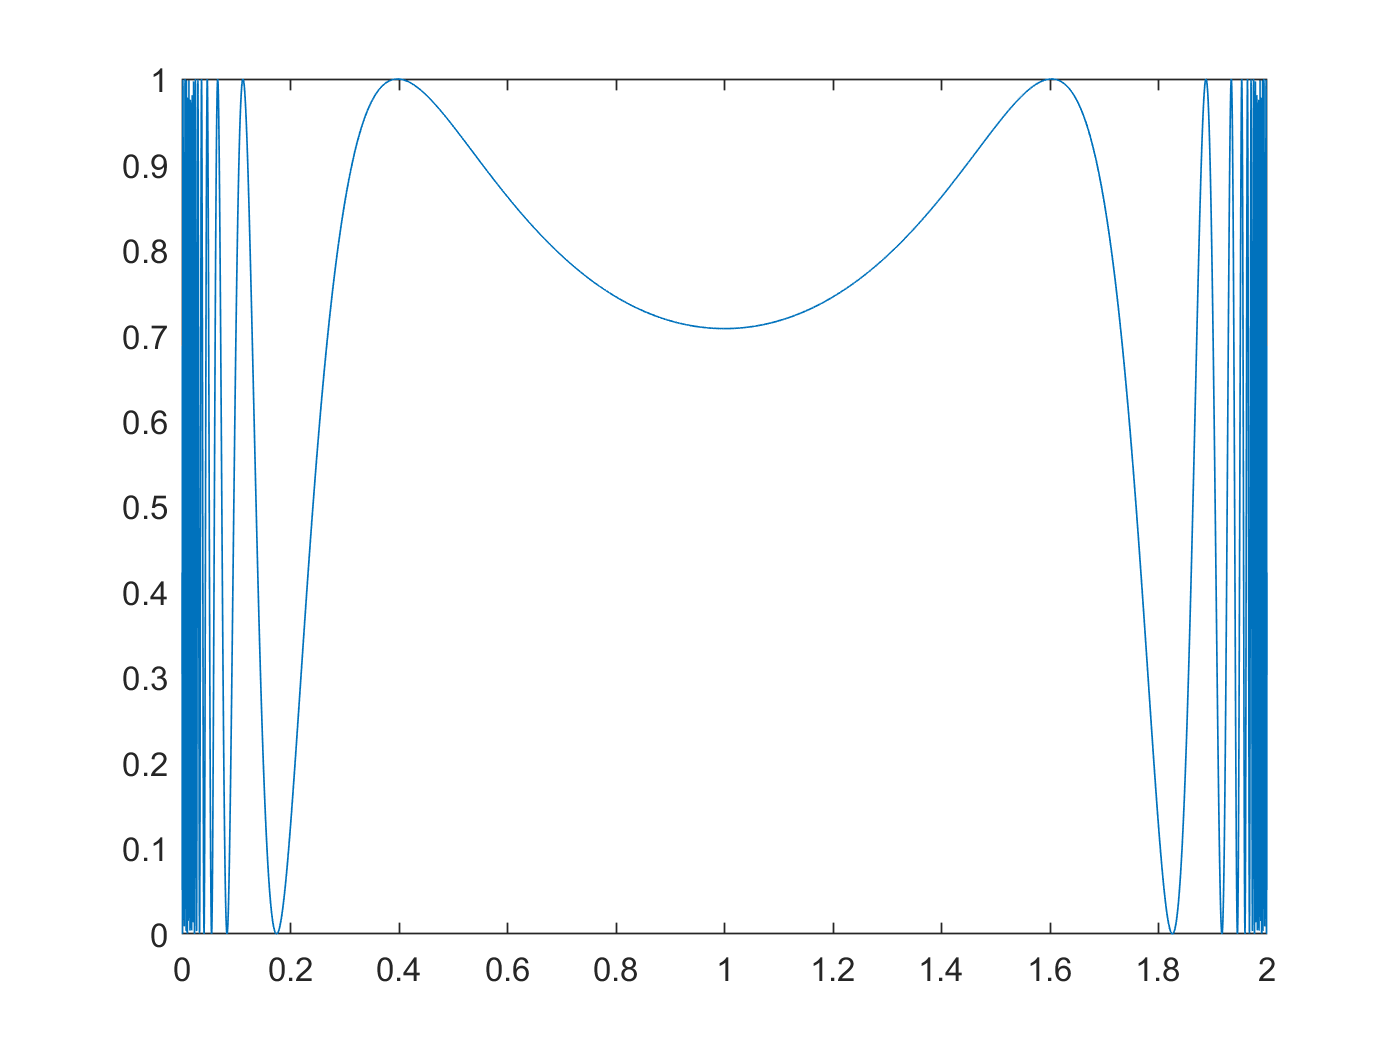

f = @(x) (sin(1./(x.*(2-x)))).^2;
x=linspace(0,2,10000)';
plot(x,f(x))

## ‘Hit or Miss’ Method

The probability that a random point ‘hits’ is equal to the proportional of the ratio of the integral value, *I*, and the closed area, *A*


$$p =\frac{I}{A}$$


The scheme: 

- Generate *N* points

- Count the number that ‘hit’, call it *k*


$$\frac{I}{A} \approx \frac{k}{N} \rightarrow I\approx \frac{kA}{N} $$


## The Error in the Hit or Miss Method

MC integration doesn’t tend to give accurate answers

- The probability of a single random point falls below the curve is *p,*and the probability it doesn’t is *1-p*

- The probability of *k* points falling below the curve and the other *N-k* points don’t is $p^k(1-p)^{N-k}$, but there are *N!/((N-k)!k!) *ways of choosing *k *points from *N *points. Therefore, the total probability *P(k)* that exactly k points below the curve is


$$P(k) = \frac{N!}{(N-k)!k!}p^k(1-p)^{N-k}$$


Which is a Binomial Distribution!!

The uncertainty (that is standard deviation of the Binomial distribution) is 

$\sigma = \sqrt{Np(1-p)} = \sqrt{\frac{I(A-I)}{N}}$'

a=0;
b=2;
N = 10000;
A = (b-a)*max(f(x)); % this finds the area of a box surrounding the function in the bounds of the integral
y = max(f(x))*rand(N,1);
k = sum(y<f(x));
I = k*A/N

I =    1.452199967883299

err = sqrt(I*(A-I)/N)

err =    0.008919165458791

## Mean Value Method

We can also take any integral


$$I = \int_{a}^{b} f(x) dx$$


And find the average value of *f(x) *over the interval `[``a,b``]`


$$\langle f\rangle = \frac{1}{b-a}\int_{a}^{b}f(x)\,dx = \frac{I}{b-a}$$



$$I = (b-a)\langle f\rangle$$


A simple way to estimate *⟨f⟩* is by sampling *N* uniform random numbers between *a* and *b, *and calculating the average of these points


$$I\approx \frac{b-a}{N}\,\sum_{i=1}^{N}f(x_i)$$


## The Error in the Mean Value Method

- The random numbers give the value of *f(x),*and the variance on the array is given by 


$$var(f) = \langle f^2\rangle - \langle f\rangle^2$$


- The variance on all the *N *points is then


$$var(f)_{tot} = N\, var(f)$$


- Calculating this quantity and taking the square root gives the standard deviation (*often referred to as the uncertainty*). 

- The uncertainty on the integral is then


$$\sigma = \frac{b-a}{N}\sqrt{N\,var(f)} = (b-a)\sqrt{\frac{var(f)}{N}}$$


a=0;
b=2;
N=10000;
xr = (b-a)*rand(N,1)+a;
I2 = (b-a)/N*sum(f(xr))

I2 =    1.455736893226244

err2 = (b-a)*std(f(xr))/sqrt(N)

err2 =    0.005216229740170

err2<err

ans = logical
   1

## Higher Dimensional Integrals

In more advanced applications, higher dimensional integrals are useful

`¡`Many financial modelspredicting values of stocks and portfolios integrate quantities over several dimensions and need to do so in a timely manner

Imagine integrating a 10-D integral taking 100 points along each dimension for a trapezoid type of method

- You would need to evaluate $100^{10} = 10^{20}$ points!!

- Instead you can use a generalized mean value theorem:


$$I \approx \frac{V}{N}\sum_{i=1}^{N} f(\vec{r}_i)$$


Where the points $r_i$ are randomly picked from the volume *V*

Consider a sphere in higher dimensions. We can calculate the volume of such spheres with the Monte Carlo simulations. Let's consider a unit sphere in *D* dimensions

D = 12;
N=D*100000;
xr = 2*rand(N,1)-1;
A = reshape(xr,[N/D,D]);
p = 0;
for k=1:N/D
    r = norm(A(k,:),2);
    if r<1
        p=p+1;
    end
end
I = 2^(D)*D*p/N

I =    1.515520000000000

true = pi^(D/2)/gamma(D/2+1)

true =    1.335262768854589

I/true

ans =    1.134997571526718